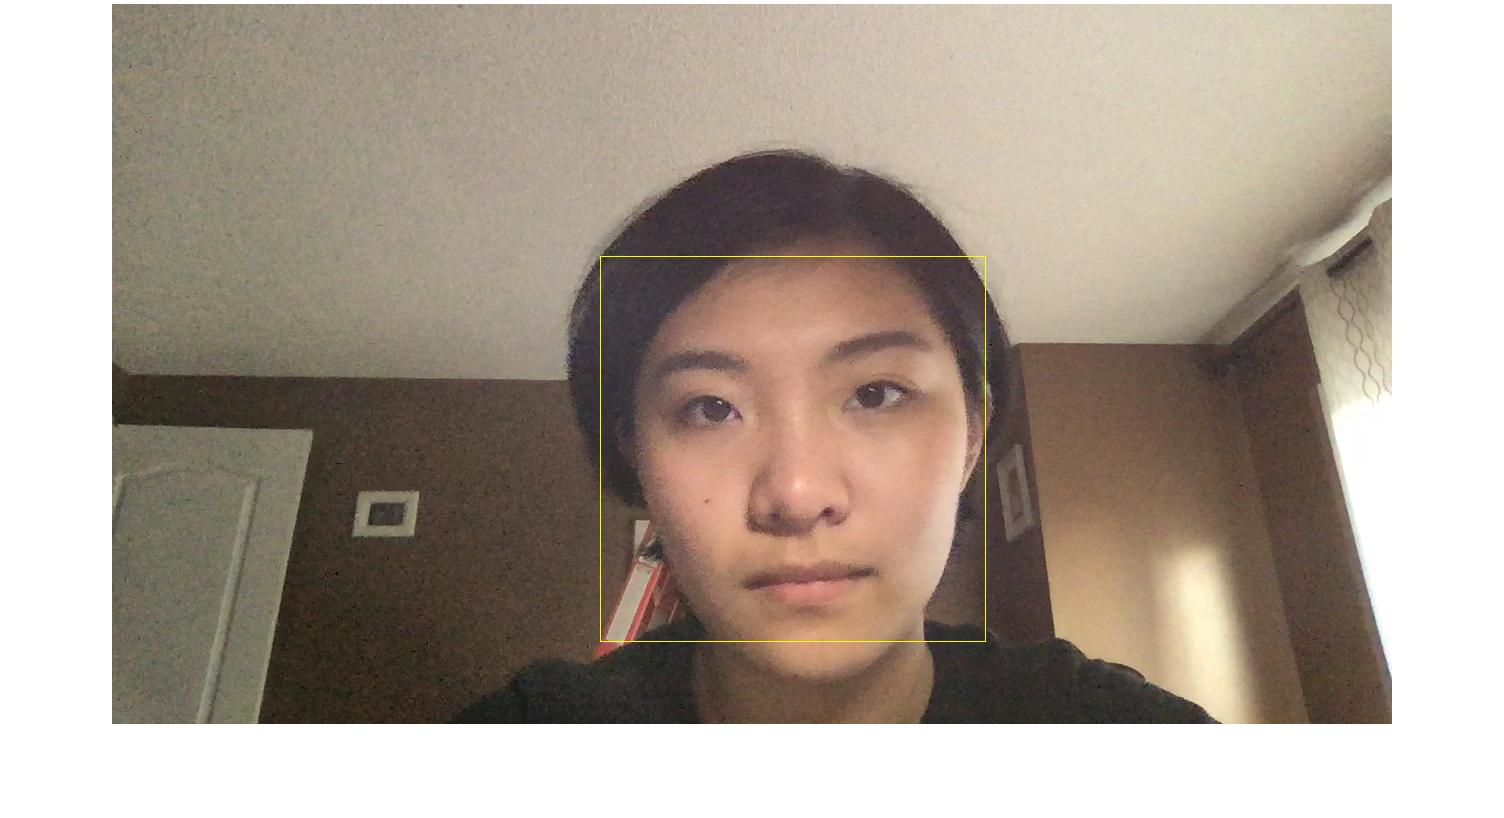

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

cam = webcam; 
videoFrame = snapshot(cam); 
bbox = step(faceDetector, videoFrame); 
% Read a video frame and run the face detector.
%videoReader = VideoReader('tilted_face.avi');
%videoFrame      = readFrame(videoReader);
%bbox            = step(faceDetector, videoFrame);

% Draw the returned bounding box around the detected face.
videoFrame = insertShape(videoFrame, 'Rectangle', bbox);
figure; imshow(videoFrame); title('Detected face');


% Convert the first box into a list of 4 points
% This is needed to be able to visualize the rotation of the object.
bboxPoints = bbox2points(bbox(1, :));

points = detectMinEigenFeatures(rgb2gray(videoFrame), 'ROI', bbox);

% Display the detected points.
figure, imshow(videoFrame), hold on, title('Detected features');
plot(points);

pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Initialize the tracker with the initial point locations and the initial
% video frame.
points = points.Location;
initialize(pointTracker, points, videoFrame);

%videoPlayer  = vision.VideoPlayer('Position',...
%    [100 100 [size(videoFrame, 2), size(videoFrame, 1)]+30]);
oldPoints = points;

while (1) %hasFrame(videoReader) 
    % get the next frame
    videoFrame = snapshot(cam); %videoFrame = readFrame(videoReader);  

    % Track the points. Note that some points may be lost.
    [points, isFound] = step(pointTracker, videoFrame);
    visiblePoints = points(isFound, :);
    oldInliers = oldPoints(isFound, :);
    
    if size(visiblePoints, 1) >= 2 % need at least 2 points
        
        % Estimate the geometric transformation between the old points
        % and the new points and eliminate outliers
        [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
            oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
        
        % Apply the transformation to the bounding box points
        bboxPoints = transformPointsForward(xform, bboxPoints);
                
        % Insert a bounding box around the object being tracked
        bboxPolygon = reshape(bboxPoints', 1, []);
        videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, ...
            'LineWidth', 2);
                
        % Display tracked points
   %     videoFrame = insertMarker(videoFrame, visiblePoints, '+', ...
     %       'Color', 'white');       
        imshow(videoFrame); 
        % Reset the points
        oldPoints = visiblePoints;
        setPoints(pointTracker, oldPoints);        
    end
    
    % Display the annotated video frame using the video player object
    %step(videoPlayer, videoFrame);
end


% Clean up
clear('cam');

release(pointTracker);